# Bootcamp Day 2 Part 1

restoredefaultpath
addpath('/usr/local/MATLAB/toolboxes/fieldtrip/')
ft_defaults
addpath(genpath('/usr/local/MATLAB/toolboxes/hcn_toolbox/'))
addpath(genpath('/usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/'))

## L4 - Anatomical reconstruction of intracranial data

Pro: high spatiotemporal precision and signal-to-noise ratio

Con: idiosyncratic and information-rich signals (unique electrode coverage, high dimensionality)

Functional and anatomical workflows are integrated in FT for ease of use and minimization of human error

## Preprocessing of MRI

- (1) determine coordinate system (ft_read_mri, ft_determine_coordsys), (2) which axis is left-right axis, (3) which direction does it go (left to right or right to left)

- realignment to ACPC space (preferred convention for freesurfer step next)

- cortical surface extraction with FreeSurfer (optional)

## Preprocessing of CT

- realignment to ACPC, via CTF

## Fusion of MRI and CT

## Electrode placement

Seamless integration between anatomical steps and neural recording steps (e.g., can provide anatomical labels to neural cfg data and when do rereferencing it will automatically update anatomical labels to match new virtual electrode locations and labels)

Can also split data by depths vs. strips & grids, do type-specific referencing and other analyses, then merge data back together

## Brain shift compensation

Electrode displacement compensated with back-projection to the cortical surface

- 'dykstra2012', 'hermes2010' (doesn't try to preserve inter-electrode distance)

- start with dykstra and use hermes if result doesn't make sense

## Spatial normalization

Matching patient brain to template brain (in MNI space or in freesurfer ['fsaverage'])

- freesurfer warp tries to maintain gyri locations of electrodes on matching gyri in template

- default normalization warps larger brain structures (e.g., lobes) to template brain, but does not take into account more local features (e.g., electrode localizations on gyri)

## Anatomical labeling

generate_electable.m download from website to loop over all electrodes and provide anatomical labels in a number of atlases

## H3 - Analysis of human ECoG and sEEG

## Procedure

The tutorial has two parallel but interrelated workflows. The first workflow entails the processing of  anatomical data. Its main activities constitute the preprocessing and  fusion of the anatomical images, and electrode placement (Steps 1-20).  Secondary activities that are also demonstrated include cortical surface extraction with FreeSurfer, brain shift compensation, spatial  normalization, and anatomical labeling (Steps 6 and 21-34). Generally,  the anatomical workflow aims to obtain estimates of the electrode  locations in relation to the individual and atlas-based brain anatomy,  which is a one-time procedure for each subject.

The second workflow focuses on improving the signal-to-noise ratio and  extracting the relevant features from the electrophysiological data,  while preparing for subsequent analyses. It minimally encompasses the  preprocessing of the neural recordings, but may also include follow-up  activities such as time- frequency and single-subject or group-level  statistical analysis (Steps 35-46). Generally, the specifics of the  functional workflow depend ultimately on the clinical or research  question at hand and contingencies in the experimental paradigm.

The two workflows become intrinsically connected for the first time  during the electrode placement activity (Step 17), which offers the  opportunity to directly link anatomical locations to electrode labels  corresponding to the neural recordings. This activity involves a  graphical user interface designed for efficient yet precise  identification of electrodes in even the most challenging cases. The  integration of the two workflows culminates in an interactive and  anatomically informed data exploration tool and the ability to represent functional and epileptiform neural activity overlaid on cortical and  subcortical surface models, in figure or video format (Steps 47-57).

## Anatomical Workflow

- Specify the subject ID. This ID will be used in the file naming, in  addition to information about the type of data (e.g., MRI, CT), the  coordinate system it is in (e.g., ACPC, MNI), and the process(es) that  were applied to it (e.g., f for fusion). For example, a CT scan that is  aligned to the ACPC coordinate system and that has just been fused with  the anatomical MRI is written out to file as subjID_CT_acpc_f.nii.

subjID = fullfile('Zenodo','SubjectUCI29');

## **Preprocessing of the anatomical MRI**

- Import the anatomical MRI into the MATLAB workspace using ft_read_mri.  The MRI comes in the format of a single file with an .img or .nii  extension, or a folder containing a series of files with a .dcm or .ima  extension (DICOM; [Supplementary File 2](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM4_ESM.pdf) of the original paper may aid in the search and visualization of a  DICOM series). For tutorial purposes, we read in the already  preprocessed MRI:

mri = ft_read_mri([subjID '_MR_acpc.nii']); % we used the dcm series

 In ft_estimate_units at line 56
 In ft_determine_units at line 107
 In ft_read_mri at line 462



- Determine the native orientation of the anatomical MRI’s left-right axis using ft_determine_coordsys (Box 3 and [Supplementary Video 1](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM6_ESM.mp4) of the original paper).

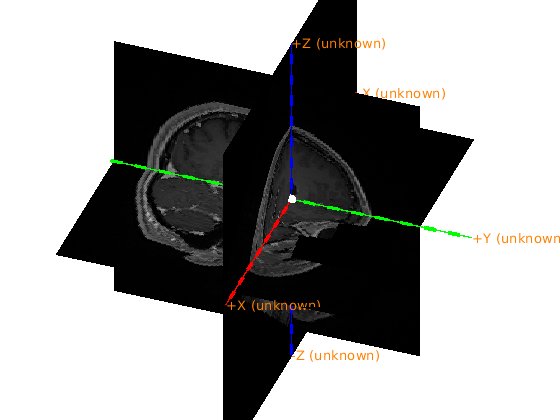

The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


ft_determine_coordsys(mri);

CRITICAL STEP To correctly fuse the MRI and CT scans at a later step,  accuracy in demarcating the right hemisphere landmark in the following  step is important for avoiding an otherwise hard to detect flip of the  scan’s left and right orientation.

- Align the anatomical MRI to the ACPC coordinate system, a preferred  convention for the FreeSurfer operation optionally used in a later step. In this coordinate system, the origin (coordinate [0,0,0]) is at the  anterior commissure (AC), the Y-axis runs along the line between the  anterior and posterior commissure (PC), and the Z-axis lies in the  midline dividing the two cerebral hemispheres. Specify the anterior and  posterior commissure, an interhemispheric location along the midline at  the top of the brain, and a location in the brain’s right hemisphere. If the scan was found to have a left-to-right orientation in the previous  step, the right hemisphere is identified as the hemisphere having larger values along the left-right axis. Vice versa, in a right-to-left  system, the right hemisphere has smaller values along that axis than its left counterpart ([Supplementary Video 2](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM7_ESM.mp4)).

cfg           = [];
cfg.method    = 'interactive';
cfg.coordsys  = 'acpc';
mri_acpc = ft_volumerealign(cfg, mri);

the input is volume data with dimensions [256 256 176]
1. To change the slice viewed in one plane, either:
   a. click (left mouse) in the image on a different plane. Eg, to view a more
      superior slice in the horizontal plane, click on a superior position in the
      coronal plane, or
   b. use the arrow keys to increase or decrease the slice number by one
2. To mark a fiducial position or anatomical landmark, do BOTH:
   a. select the position by clicking on it in any slice with the left mouse button
   b. identify it by pressing the letter corresponding to the fiducial/landmark:
      press a for ac, p for pc, z for xzpoint
      press r for an extra control point that should be on the right side
   You can mark the fiducials multiple times, until you are satisfied with the positions.
3. To change the display:
   a. press c on keyboard to toggle crosshair visibility
   b. press f on keyboard to toggle fiducial visibility
   c. press + or - on (numeric) keyboard to change the co

 In ft_headcoordinates at line 237
 In ft_volumerealign at line 1020

the call to "ft_volumerealign" took 26 seconds and required the additional allocation of an estimated 219 MB


- Write the preprocessed anatomical MRI out to file.

cfg           = [];
cfg.filename  = [subjID '_MR_acpc'];
cfg.filetype  = 'nifti';
cfg.parameter = 'anatomy';
ft_volumewrite(cfg, mri_acpc);

the input is volume data with dimensions [256 256 176]
the call to "ft_volumewrite" took 0 seconds and required the additional allocation of an estimated 1 MB


## **Cortical surface extraction with FreeSurfer (optional)**

- Execute FreeSurfer’s recon-all functionality from the Linux or MacOS  terminal (Windows via VirtualBox), or from the MATLAB command window as  below. This set of commands will create a folder named ‘freesurfer’ in  the subject directory, with subdirectories containing a multitude of  FreeSurfer-generated files.

For tutorial purposes, the example dataset contains the output from  FreeSurfer, a folder named ‘freesurfer’, for continuation with the  protocol. You can therefore skip this time-consuming computation and  continue with the next step.

fshome     = '/usr/local/freesurfer/';
subdir     = '/usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Zenodo';
mrfile     = fullfile('Zenodo','SubjectUCI29_MR_acpc.nii');
system(['export FREESURFER_HOME=' fshome '; ' ...
'source $FREESURFER_HOME/SetUpFreeSurfer.sh; ' ...
'mri_convert -c -oc 0 0 0 ' mrfile ' ' [subdir '/tmp.nii'] '; ' ...
'recon-all -i ' [subdir '/tmp.nii'] ' -s ' 'freesurfer' ' -sd ' subdir ' -all'])

mri_convert.bin -c -oc 0 0 0 Zenodo/SubjectUCI29_MR_acpc.nii /usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Zenodo2/tmp.nii 
$Id: mri_convert.c,v 1.226 2016/02/26 16:15:24 mreuter Exp $
reading from Zenodo/SubjectUCI29_MR_acpc.nii...
TR=0.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, -2.62484e-10, 2.52605e-09)
j_ras = (-7.72369e-19, -0.99763, 0.0688021)
k_ras = (-4.64343e-18, 0.0688021, 0.99763)
changing data type from short to uchar (noscale = 0)...
MRIchangeType: Building histogram 
Reslicing using trilinear interpolation 
writing to /usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Zenodo2/tmp.nii...
niiWrite(): error opening file /usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Zenodo2/tmp.nii
ERROR: failure writing /usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Zenodo2/tmp.nii
ERROR: cannot find /usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Zenodo2/tmp.nii
Linux hcnlab 4.15.0-46-generic #49-Ubuntu SMP Wed Feb 6 09:33:07 UTC 2019 x86_64

ans = 1

PAUSE POINT FreeSurfer’s fully automated segmentation and cortical  extraction of the anatomical MRI currently may take up 10 hours or more.

- Import the extracted cortical surfaces into the MATLAB workspace and  examine their quality. Repeat the following code using rh.pial to  visualize the pial surface of the right hemisphere.

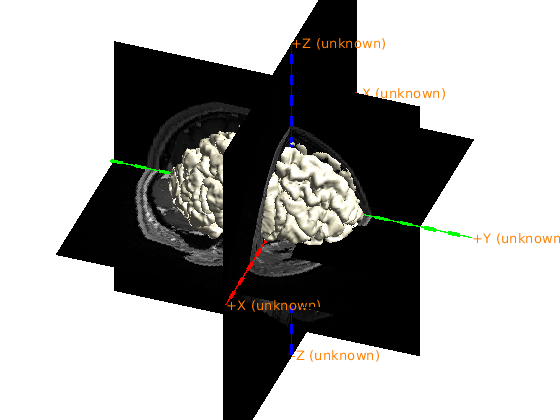

pial_lh = ft_read_headshape('freesurfer/surf/lh.pial');
pial_lh.coordsys = 'acpc';
ft_plot_mesh(pial_lh);
lighting gouraud;
camlight;

pial_rh = ft_read_headshape('freesurfer/surf/rh.pial');
pial_rh.coordsys = 'acpc';
ft_plot_mesh(pial_rh);
lighting gouraud;
camlight;

- Import the FreeSurfer-processed MRI into the MATLAB workspace for the  purpose of fusing with the CT scan at a later step, and specify the  coordinate system to which it was aligned in Step 4.

% fsmri_acpc = ft_read_mri('freesurfer/mri/T1.mgz');
fsmri_acpc = ft_read_mri([subjID '_MR_acpc.nii']);

 In ft_estimate_units at line 56
 In ft_determine_units at line 107
 In ft_read_mri at line 462



fsmri_acpc.coordsys = 'acpc';

## **Preprocessing of the anatomical CT**

- Import the anatomical CT into the MATLAB workspace. Similar to the MRI,  the CT scan comes in the format of a single file with an .img or .nii  extension, or a folder containing a series of files with a .dcm or .ima  extension ([Supplementary File 2](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM4_ESM.pdf) may aid in the search and visualization of a DICOM series). For tutorial purposes, we read in the already preprocessed CT:

ct = ft_read_mri([subjID '_CT_acpc_f.nii']); % we used the dcm series

 In ft_estimate_units at line 56
 In ft_determine_units at line 107
 In ft_read_mri at line 462



- In case this cannot be done on the basis of knowledge of the  laterality of electrode implantation, determine the native orientation  of the anatomical CT’s left- right axis using ft_determine_coordsys,  similarly to how it was done with the anatomical MRI in Step 3 (Box 3  and [Supplementary Video 1](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM6_ESM.mp4)).

CRITICAL STEP To correctly fuse the MRI and CT scans at a later step, accuracy in demarcating the right and left preauricular landmark in the following step is important for avoiding an otherwise hard to detect  flip of the scan’s left and right orientation.

- Align the anatomical CT to the CTF head surface coordinate system by  specifying the nasion (at the root of the nose), left and right  preauricular points (just in front of the ear canals), and an  interhemispheric location along the midline at the top of the brain ([Supplementary Video 3](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM8_ESM.mp4)). The CT scan is initially aligned to the CTF head surface coordinate  system given that the ACPC coordinate system used for the MRI relies on  neuroanatomical landmarks that are not visible in the CT.

cfg           = [];
cfg.method    = 'interactive';
cfg.coordsys  = 'ctf';
ct_ctf = ft_volumerealign(cfg, ct);

the input is volume data with dimensions [512 199 512]


1. To change the slice viewed in one plane, either:
   a. click (left mouse) in the image on a different plane. Eg, to view a more
      superior slice in the horizontal plane, click on a superior position in the
      coronal plane, or
   b. use the arrow keys to increase or decrease the slice number by one
2. To mark a fiducial position or anatomical landmark, do BOTH:
   a. select the position by clicking on it in any slice with the left mouse button
   b. identify it by pressing the letter corresponding to the fiducial/landmark:
      press n for nas, l for lpa, r for rpa
      press z for an extra control point that should have a positive z-value
   You can mark the fiducials multiple times, until you are satisfied with the positions.
3. To change the display:
   a. press c on keyboard to toggle crosshair visibility
   b. press f on keyboard to toggle fiducial visibility
   c. press + or - on (numeric) keyboard to change the color range's upper limit
4. To finalize markers and qui

- Automatically convert the CT’s coordinate system into an approximation  of the ACPC coordinate system, the same system the anatomical MRI was  aligned to.

ft_hastoolbox('spm12',1);
ct_acpc = ft_convert_coordsys(ct_ctf, 'acpc');

converting the coordinate system from ctf to acpc
using 'OldNorm' normalisation
Rescaling NIFTI: slope = 0.00342945, intercept = 0
Smoothing by 0 & 8mm..
Coarse Affine Registration..
Fine Affine Registration..


## **Fusion of the CT with the MRI**

- Fuse the CT with the MRI, a necessary step to link the electrode  locations in the anatomical CT to their corresponding locations in the  anatomical MRI. Given that both scans are from the same subject and  their common denominator is the skull, a rigid body transformation  suffices for their alignment under normal circumstances (the default  technique when using the SPM-method in FieldTrip).

the input is volume data with dimensions [512 199 512]

SPM12: spm_coreg (v6435)                           15:19:21 - 02/08/2019
Completed                               :          15:20:47 - 02/08/2019


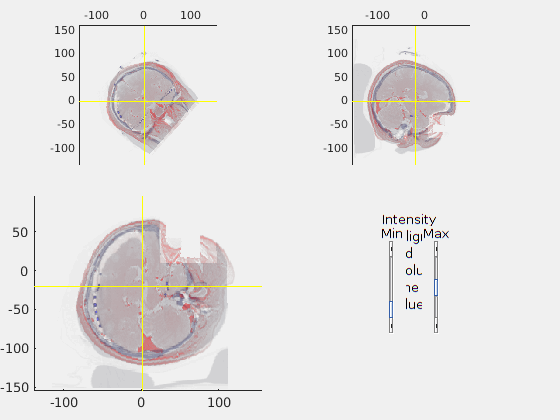

the call to "ft_volumerealign" took 93 seconds and required the additional allocation of an estimated 1781 MB


cfg             = [];
cfg.method      = 'spm';
cfg.spmversion  = 'spm12';
cfg.coordsys    = 'acpc';
cfg.viewresult  = 'yes';
ct_acpc_f = ft_volumerealign(cfg, ct_acpc, fsmri_acpc);

NOTE: My fusion is not perfect. Need to play around with it more, but continuing on with tutorial for sake of completion.

- Carefully examine the interactive figure that is produced after the  coregistration is completed, showing the MRI and fused CT superimposed. A successful fusion will show tight interlocking of CT-positive skull (in blue) and MRI-positive brain and skin tissue (in red).

CRITICAL STEP Accuracy of the fusion operation is important for  correctly placing the electrodes in anatomical context in a following  step.

- Write the MRI-fused anatomical CT out to file.

cfg           = [];
cfg.filename  = [subjID '_CT_acpc_f'];
cfg.filetype  = 'nifti';
cfg.parameter = 'anatomy';
ft_volumewrite(cfg, ct_acpc_f);

the input is volume data with dimensions [512 199 512]
the call to "ft_volumewrite" took 1 seconds and required the additional allocation of an estimated 97 MB


## **Electrode placement**

- Import the header information from the recording file, if possible. By  giving the electrode labels originating from the header as input to  ft_electrodeplacement in the next step, the labels will appear as a  to-do list during the interactive electrode placement activity. A second benefit is that the electrode locations can be directly assigned to  labels collected from the recording file, obviating the need to sort and rename electrodes to match the electrophysiological data.

For tutorial purposes, load the header, which is normally obtained using ft_read_header, and continue with step 17: load([subjID ‘_hdr.mat’]);

% hdr = ft_read_header(<path to recording file>); % use when you have your
                                                  % own data
load([subjID '_hdr.mat']);                        % use for tutorial

- Localize the electrodes in the post-implant CT with  ft_electrodeplacement, shown in the figure below. Clicking an electrode  label in the list will directly assign that label to the current  crosshair location ([Supplementary Video 4](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM9_ESM.mp4)). Several in-app features facilitate efficient yet precise navigation of  the anatomical image, such as a zoom mode, a magnet option that  transports the crosshair to the nearest weighted maximum with subvoxel  accuracy (or minimum in case of a post-implant MRI), and an interactive  three-dimensional scatter figure that is linked to the two-dimensional  volume representations. Furthermore, passing on the pre-implant MRI,  fsmri_acpc, to ft_electrodeplacement allows toggling between CT and MRI  views for the identification of specific electrodes based on their  anatomical location. Generally, electrode #1 is the electrode farthest  away from the craniotomy or burr hole in case of depths and single-row  strips. Careful notes taken during surgery and recording are critical  for determining the numbering of grid and multi-row strip electrodes.

cfg         = [];
cfg.channel = hdr.label;
elec_acpc_f = ft_electrodeplacement(cfg, ct_acpc_f, fsmri_acpc);

the input is volume data with dimensions [512 199 512]
the input is volume data with dimensions [256 256 176]


1. Orthoplot viewing options:
   a. use the left mouse button to navigate the image, or
   b. use the arrow keys to increase or decrease the slice number by one
2. Orthoplot placement options:
   a. click an electrode label in the list to assign it to the crosshair location, or
   b. doubleclick a previously assigned electrode label to remove its marker
3. To finalize, close the window or press q on the keyboard
4. See Stolk, Griffin et al. (2017) for further electrode processing options


 clicked at [-52.0 -64.8 25.6], peakweighted magnetized adjustment [-0.5 -0.0 -0.5] mm
 crosshair at [-52.5 -64.8 25.1] mm
 clicked at [-55.6 -63.4 15.8], peakweighted magnetized adjustment [0.5 -1.1 0.6] mm
 crosshair at [-55.1 -64.5 16.5] mm
the call to "ft_electrodeplacement" took 160 seconds and required the additional allocation of an estimated 1020 MB


NOTE: In this live script, I think I switched LHH with LTH

- Examine whether the variables in resulting electrode structure  elec_acpc_f match the recording parameters, e.g., the number of channels stored in the label field. The electrode and channel positions are  stored in the elecpos and chanpos fields, respectively. The elecpos  field contains the original electrode positions. With exception of  possible brain shift compensation, this field is not adjusted. The  channel positions in the chanpos field are initially identical to the  electrode positions but may be updated to accommodate offline  adjustments in channel combinations, i.e. during re-montaging. For  bipolar iEEG data, the best considered channel position is in between  the two corresponding electrode positions. The chanpos field is used for overlaying the neural data on (sub-)cortical models during data  visualization. The tra field is a matrix with the weight of each  electrode into each channel, which at this stage merely is an identity  matrix reflecting one-to-one mappings between electrodes and channels.

load([subjID '_elec_acpc_f.mat'])
elec_acpc_f

elec_acpc_f = struct with fields:
        unit: 'mm'
    coordsys: 'acpc'
       label: {152×1 cell}
     elecpos: [152×3 double]
     chanpos: [152×3 double]
         tra: [152×152 double]
         cfg: [1×1 struct]


- Visualize the MRI along with the electrodes and their labels and examine whether they show expected behavior.

ft_plot_ortho(fsmri_acpc.anatomy, 'transform', fsmri_acpc.transform, 'style', 'intersect');

 In ft_estimate_units at line 56
 In ft_plot_slice at line 210
 In ft_plot_ortho at line 165



 In ft_estimate_units at line 56
 In ft_plot_slice at line 210
 In ft_plot_ortho at line 168



 In ft_estimate_units at line 56
 In ft_plot_slice at line 210
 In ft_plot_ortho at line 171



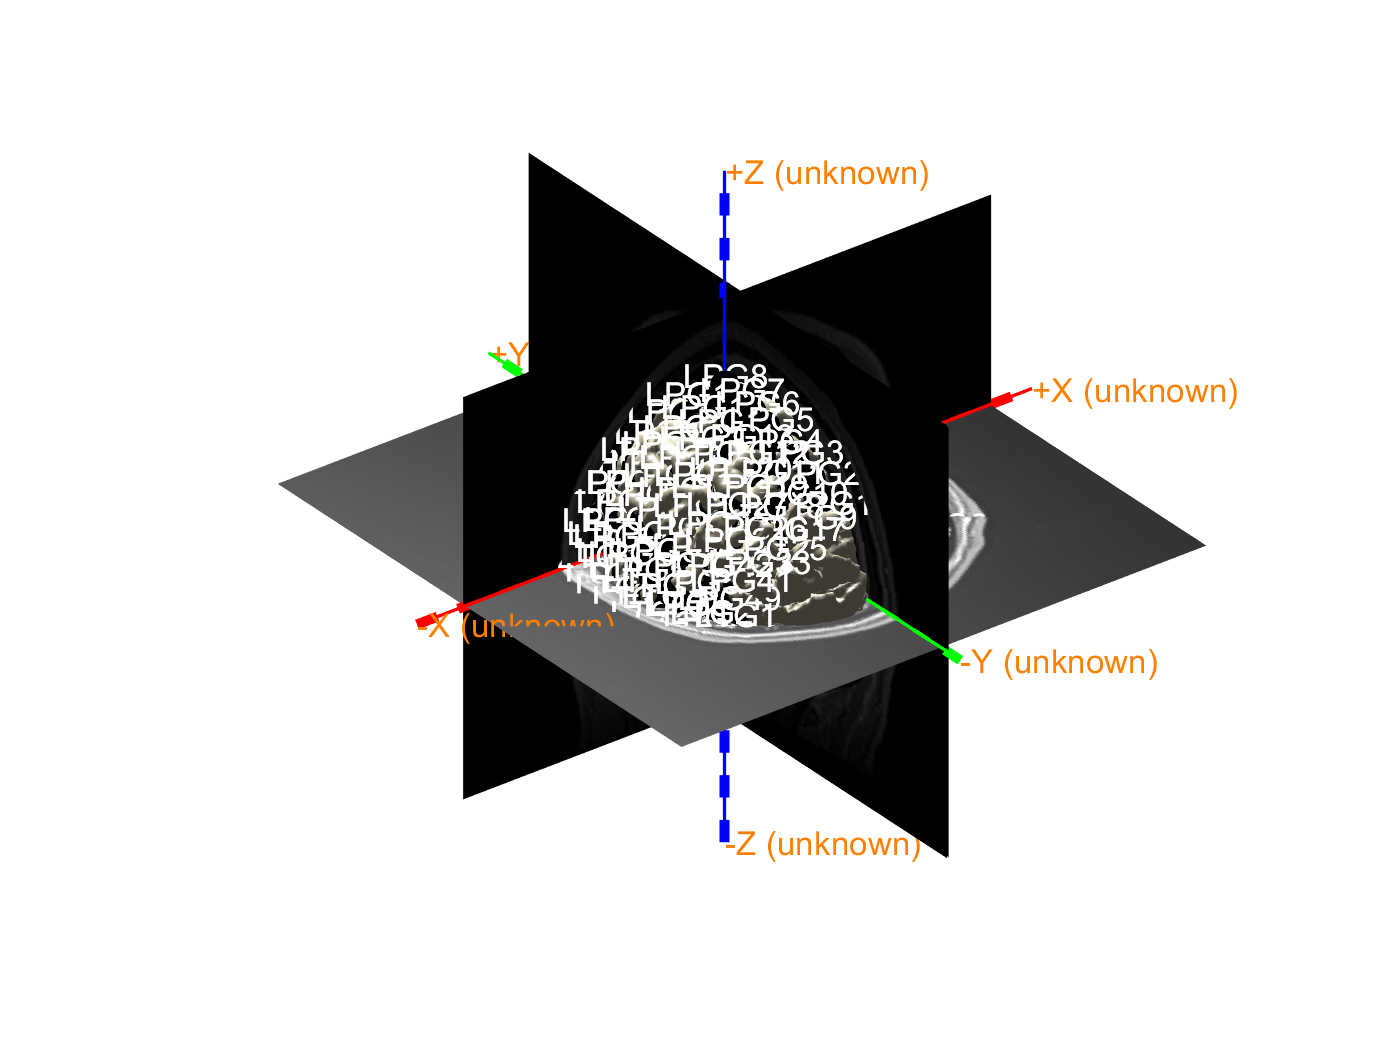

ft_plot_sens(elec_acpc_f, 'label', 'on', 'fontcolor', 'w');

- Save the resulting electrode information to file.

save([subjID '_elec_acpc_f.mat'], 'elec_acpc_f');

## **Brain shift compensation (optional for cortical grids and strips)**

In case of “brain shift”, i.e. the inward displacement of brain tissue  and electrodes due to pressure changes related to the craniotomy,  realignment of electrode grids to the pre-implant cortical surface may  be necessary. To prevent inwardly displaced electrodes from being  incorrectly placed in nearby cortical sulci during back-projection,  create a smooth hull around the cortical mesh generated by FreeSurfer.  This hull tracks the (exposed) outer surface on which the cortical grid  rested.

The computation of the cortical hull takes some time. For tutorial  purposes, load the hull from file and continue with step 23:  load([subjID ‘_hull_lh.mat’]);

%%%% code for using freesurfer
% cfg           = [];
% cfg.method    = 'cortexhull';
% cfg.headshape = 'freesurfer/surf/lh.pial';
% cfg.fshome    = /usr/local/freesurfer/; % for instance, '/Applications/freesurfer'
% hull_lh = ft_prepare_mesh(cfg);

%%% for tutorial
load([subjID '_hull_lh.mat']);

- Save the hull to file.

%%% only for code using freesurfer
% save([subjID '_hull_lh.mat'], hull_lh);

- Project the electrode grids to the surface hull of the implanted  hemisphere. Given that different grids can move independently from one  another and that the projection algorithm specified in cfg.warp  considers the global electrode configuration of a grid, it is  recommended to realign electrode grids individually by running separate  realignment procedures for each grid. Here, we realign the electrodes of the left parietal grid followed by the electrodes of the left temporal  grid (LPG and LTG respectively) and store the updated grid electrode  information in a new variable together with the unaltered coordinates of the depth electrodes.

elec_acpc_fr = elec_acpc_f;
grids = {'LPG*', 'LTG*'};
for g = 1:numel(grids)
    cfg             = [];
    cfg.channel     = grids{g};
    cfg.keepchannel = 'yes';
    cfg.elec        = elec_acpc_fr;
    cfg.method      = 'headshape';
    cfg.headshape   = hull_lh;
    cfg.warp        = 'dykstra2012';
    cfg.feedback    = 'yes';
    elec_acpc_fr = ft_electroderealign(cfg);
end

using electrodes specified in the configuration
using warp algorithm described in Dykstra et al. 2012 Neuroimage PMID: 22155045
creating electrode pairs based on electrode positions

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0    193            0        10.32                                         Infeasible start point
    1    386      39.1502       0.4961            1       0.0398          8.5   
    2    583      36.2606       0.5026       0.0625        -6.05         25.6   

Local minimum possible. Constraints satisfied.

fmincon stopped because the predicted change in the objective function
is less than the

- Visualize the cortex and electrodes together and examine whether they show expected behavior (figure below).

CRITICAL STEP Accuracy of the realignment operation is important for  correctly placing the electrodes in anatomical context in a following  step.

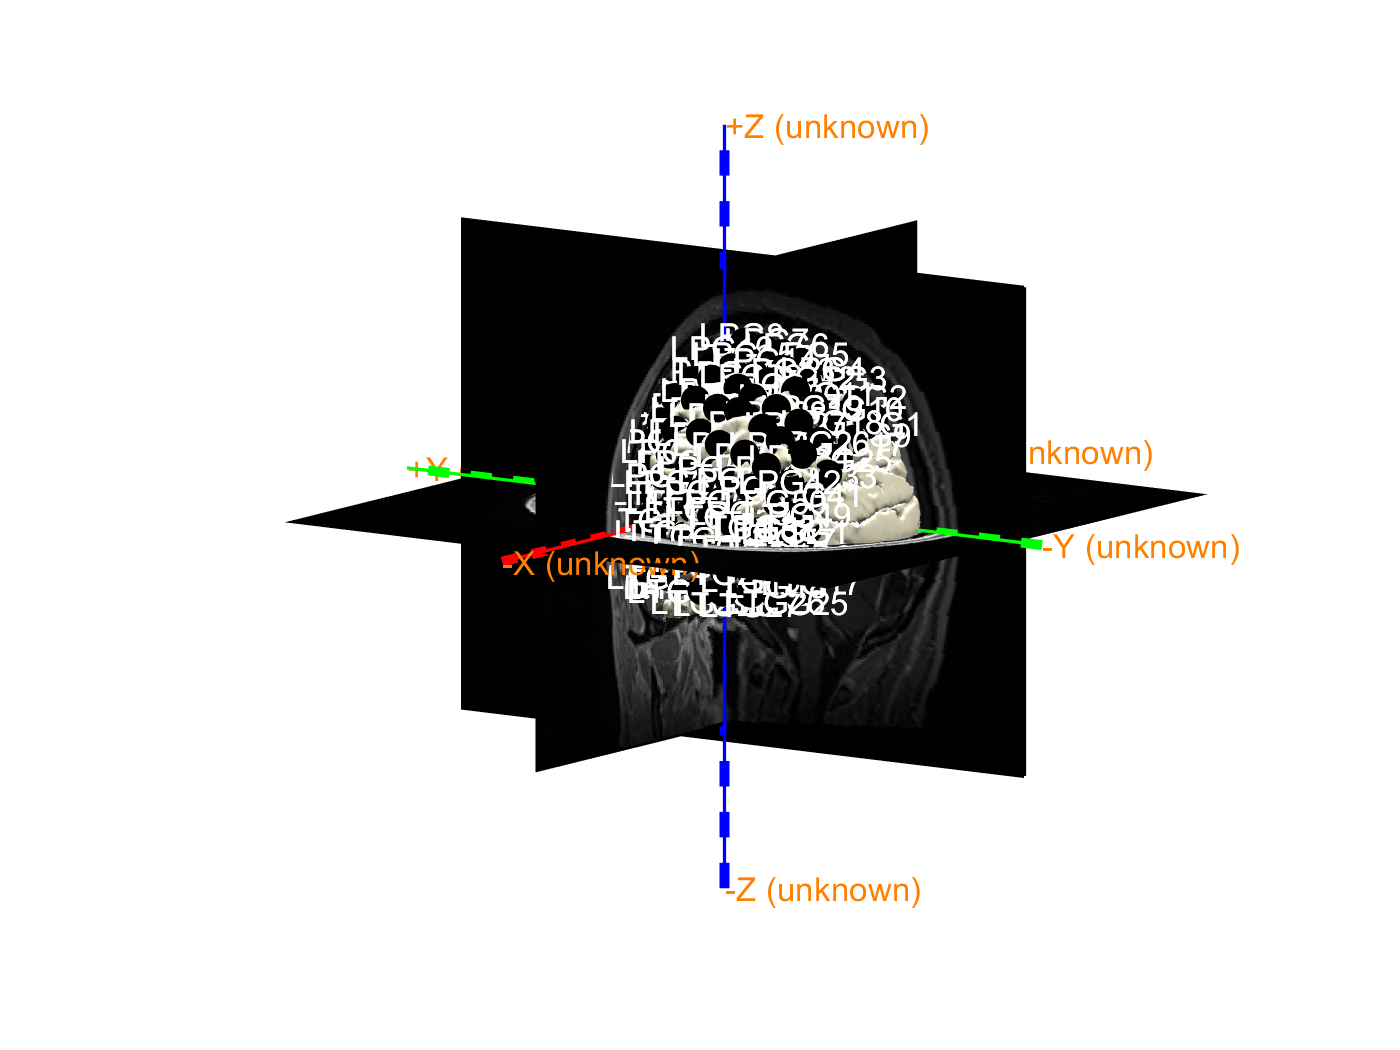

ft_plot_mesh(pial_lh);
ft_plot_sens(elec_acpc_fr);
view([-55 10]);
material dull;
lighting gouraud;
camlight;

- Save the updated electrode information to file.

save([subjID '_elec_acpc_fr.mat'], 'elec_acpc_fr');

## **Volume-based registration (optional) - Non-freesurfer based**

- To generalize the electrode coordinates to other brains or MNI-based  neuroanatomical atlases in a later step, register the subject’s brain to the standard MNI brain. The volume-based registration technique  considers the overall geometry of the brain and can be used for the  spatial normalization of all types of electrodes, whether depth or on  the surface.

cfg            = [];
cfg.nonlinear  = 'yes';
cfg.spmversion = 'spm12';
fsmri_mni = ft_volumenormalise(cfg, fsmri_acpc);

the input is volume data with dimensions [256 256 176]
performing the normalisation
warping the individual anatomy to the template anatomy
Smoothing by 0 & 8mm..
Coarse Affine Registration..
Fine Affine Registration..
3D CT Norm...
 iteration  1:  FWHM =  22.66 Var = 63.3914
 iteration  2:  FWHM =  17.65 Var = 15.6964
 iteration  3:  FWHM =  17.23 Var = 13.6093
 iteration  4:  FWHM =  17.04 Var = 12.7969
 iteration  5:  FWHM =  16.89 Var = 12.2925
 iteration  6:  FWHM =  16.79 Var = 11.9691
 iteration  7:  FWHM =  16.71 Var = 11.7404
 iteration  8:  FWHM =  16.66 Var = 11.6035
 iteration  9:  FWHM =  16.62 Var = 11.5007
 iteration 10:  FWHM =  16.58 Var = 11.4057
 iteration 11:  FWHM =  16.56 Var = 11.3529
 iteration 12:  FWHM =  16.54 Var = 11.3149
 iteration 13:  FWHM =  16.53 Var = 11.2911
 iteration 14:  FWHM =  16.52 Var = 11.2593
 iteration 15:  FWHM =   16.5 Var = 11.2271
 iteration 16:  FWHM =  16.49 Var = 11.1992
creating the normalized volumes

SPM12: spm_write_sn (v4878)    

- Use the resulting deformation parameters to obtain the electrode positions in standard MNI space.

elec_mni_frv = elec_acpc_fr;
elec_mni_frv.elecpos = ft_warp_apply(fsmri_mni.params, elec_acpc_fr.elecpos, 'individual2sn');
elec_mni_frv.chanpos = ft_warp_apply(fsmri_mni.params, elec_acpc_fr.chanpos, 'individual2sn');
elec_mni_frv.coordsys = 'mni';

- Visualize the cortical mesh extracted from the standard MNI brain  along with the spatially normalized electrodes and examine whether they  show expected behavior given the electrodes’ original anatomical  locations (top right in the figure below).

CRITICAL STEP Accuracy of the spatial normalization step is important for correctly overlaying the electrode positions with a brain atlas in a following step.

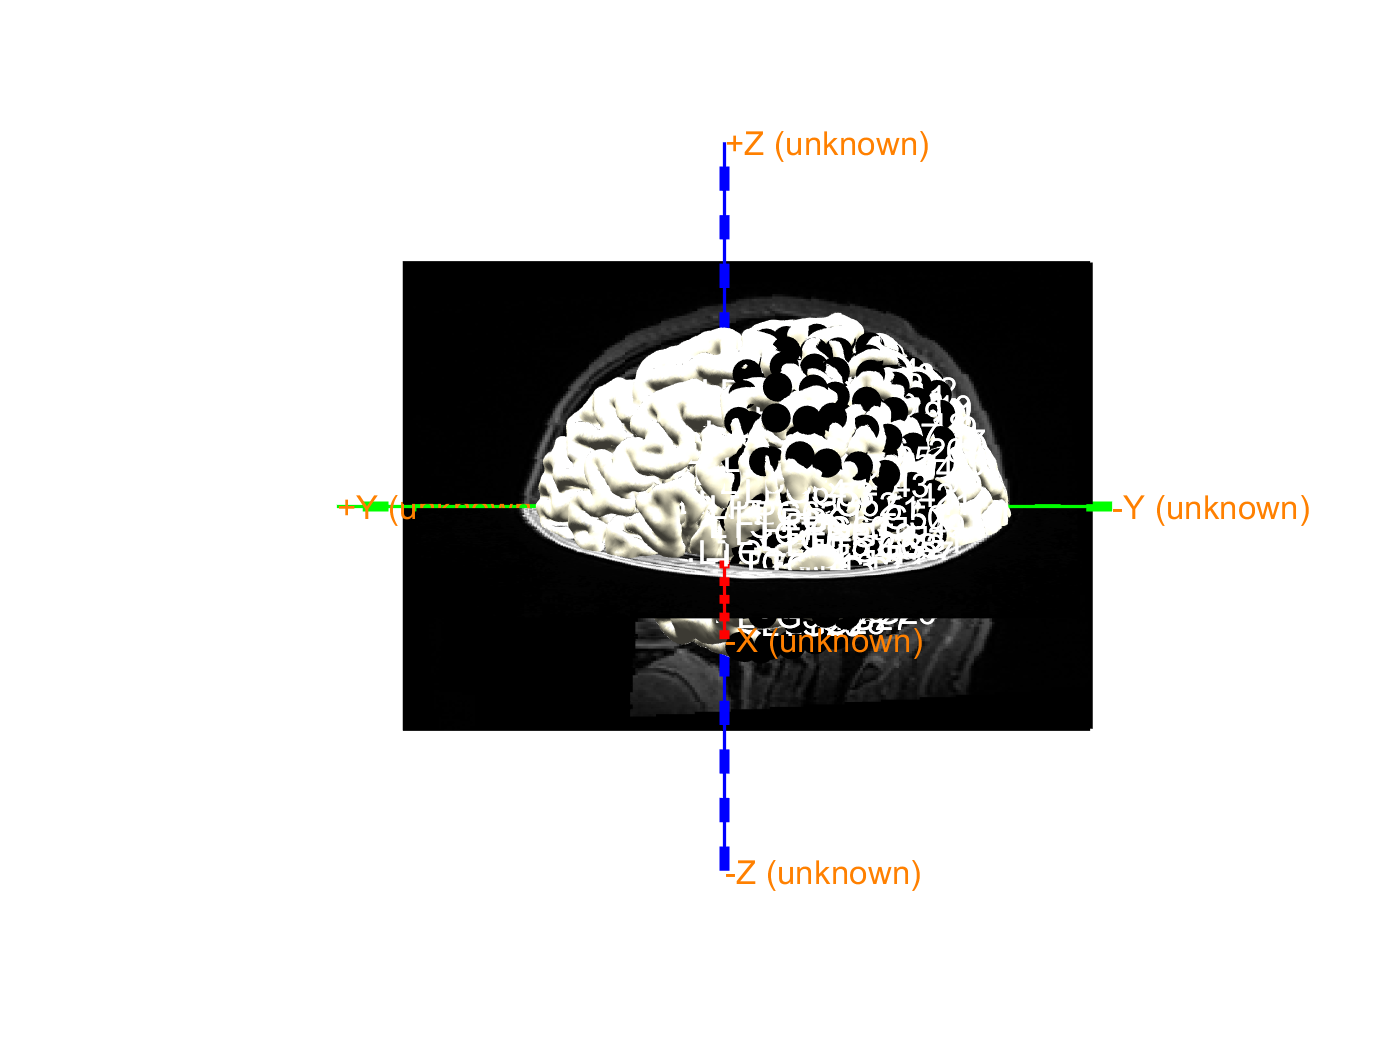

[ftver, ftpath] = ft_version;
load([ftpath filesep 'template/anatomy/surface_pial_left.mat']);
ft_plot_mesh(mesh);
ft_plot_sens(elec_mni_frv);
view([-90 20]);
material dull;
lighting gouraud;
camlight;

- Save the normalized electrode information to file.

save([subjID '_elec_mni_frv.mat'], 'elec_mni_frv');

## **Surface-based registration (optional for surface electrodes) - requires freesurfer (can't use directly on Windows)**

- To generalize the electrode coordinates to other brains in a later step, map the electrodes onto FreeSurfer’s fsaverage brain. The surface-based registration technique solely considers the curvature patterns of the  cortex and thus can be used for the spatial normalization of electrodes  located on or near the cortical surface. In the example case, this  pertains to all electrodes of the left parietal and temporal grids.

% cfg           = [];
% cfg.channel   = {'LPG*', 'LTG*'};
% cfg.elec      = elec_acpc_fr;
% cfg.method    = 'headshape';
% cfg.headshape = 'freesurfer/surf/lh.pial';
% cfg.warp      = 'fsaverage';
% cfg.fshome    = /usr/loca/freesurfer/; % for instance, '/Applications/freesurfer'
% elec_fsavg_frs = ft_electroderealign(cfg);

- Visualize FreeSurfer’s fsaverage brain along with the spatially  normalized electrodes and examine whether they show expected behavior  (bottom right in the figure below).

CRITICAL STEP Accuracy of the spatial normalization step is important for correctly overlaying the electrode positions with a brain atlas in a following step.

% fspial_lh = ft_read_headshape([cfg.fshome '/subjects/fsaverage/surf/lh.pial']);
% fspial_lh.coordsys = 'fsaverage';
% ft_plot_mesh(fspial_lh);
% ft_plot_sens(elec_fsavg_frs);
% view([-90 20]);
% material dull;
% lighting gouraud;
% camlight;

- Save the normalized electrode information to file.

% save([subjID '_elec_fsavg_frs.mat'], 'elec_fsavg_frs');

## **Anatomical labeling (optional)**

- FieldTrip supports looking up the anatomical or functional labels  corresponding to the electrodes in a number of atlases, including the  AFNI Talairach Tournoux atlas, the AAL atlas, the BrainWeb data set, the JuBrain cytoarchitectonic atlas, the VTPM atlas, and the Brainnetome  atlas, in addition to the subject- tailored Desikan-Killiany and  Destrieux atlases produced by FreeSurfer. Given that no two electrodes  end up in the exact same location across subjects due to  inter-individual variability in electrode coverage and brain anatomy,  atlases are particularly useful for the systematic combination of neural activity from different subjects in a so-called region of interest  (ROI) analysis. With exception of the above FreeSurfer-based atlases,  the atlases are in MNI coordinate space and require the electrodes to be spatially normalized (Steps 26 through 27). First, import an atlas of  interest, e.g., the AAL atlas, into the MATLAB workspace.   

atlas = ft_read_atlas([ftpath filesep 'template/atlas/aal/ROI_MNI_V4.nii']);

Rescaling NIFTI: slope = 1, intercept = 0


- Look up the corresponding anatomical label of an electrode of interest,  e.g., electrode LHH1, targeting the left hemisphere’s hippocampus. [Supplementary File 3](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM5_ESM.pdf) represents a tool that automatically overlays all channels in an  electrode structure with all of the above atlases and stores the  resulting anatomical labels in an excel table (e.g.,  SubjectUCI29_electable.xlsx in the zip file).

cfg            = [];
cfg.roi        = elec_mni_frv.chanpos(match_str(elec_mni_frv.label,'LHH1'),:);
cfg.atlas      = atlas;
cfg.inputcoord = 'mni';
cfg.output     = 'label';
labels = ft_volumelookup(cfg, atlas);

 In ft_checkconfig at line 144
 In ft_volumelookup at line 117

2 voxels at same distance of poi, taking first voxel
coordinates of voi: -22.0  -14.0 -36.0
the call to "ft_volumelookup" took 0 seconds



[~, indx] = max(labels.count);
labels.name(indx)

ans = 1×1 cell array
    {'no_label_found'}


% output of labels.name(indx) should have been 'ParaHippocampal_L'. i
% messed up with electrode placement/image fusion

NOTE: I messed upe with electrode placement and/or image fusion. Therefore my labels.name(indx) is 'no_label_found'

## Functional workflow

## **Preprocessing of the neural recordings**

- Define the trials, that is, the segments of data that will be used for  further processing and analysis. This step produces a matrix cfg.trl  containing for each segment the begin and end sample in the recording  file. In the case of the example provided in the shared data, the  segments of interest begin 400 ms before tone onset, are marked with a  ‘4’ in the trigger channel, and end 900 ms thereafter.

Raw recording files are not shared, in order to protect the subject’s  identity. For tutorial purposes, load the preprocessed data, which is  the product of steps 35 & 36, and continue with step 37:  load([subjID ‘_data.mat’], ‘data’);

%%% for when we use our own data
% cfg                     = [];
% cfg.dataset             = <path to recording file>;
% cfg.trialdef.eventtype  = 'TRIGGER';
% cfg.trialdef.eventvalue = 4;
% cfg.trialdef.prestim    = 0.4;
% cfg.trialdef.poststim   = 0.9;
% cfg = ft definetrial(cfg);

%%% for use with tutorial
 load([subjID '_data.mat'], 'data');
 

- Import the data segments of interest into the MATLAB workspace and  filter the data for high-frequency and power line noise (see the  documentation of ft_preprocessing for filtering options).

%%% for when we use our own data
% cfg.demean         = 'yes';
% cfg.baselinewindow = 'all';
% cfg.lpfilter       = 'yes';
% cfg.lpfreq         = 200;
% cfg.padding        = 2;
% cfg.padtype        = 'data';
% cfg.bsfilter       = 'yes';
% cfg.bsfiltord      = 3;
% cfg.bsfreq         = [59 61; 119 121; 179 181];
% data = ft_preprocessing(cfg);

- Examine whether the variables in the output data structure match the  recording and preprocessing parameters, i.e. the sampling rate  (fsample), number of recording channels (label), and segmentation into  the experiment’s twenty-six trials (trial, and their respective time  axes in time).

data

data = struct with fields:
       fsample: 5000
    sampleinfo: [26×2 double]
         trial: {1×26 cell}
          time: {1×26 cell}
         label: {152×1 cell}
          elec: [1×1 struct]
     trialinfo: [26×1 double]


- Add the elec structure originating from the anatomical workflow and save the preprocessed electrophysiological data to file. The advantage of  adding the electrode information at this stage is that it will be kept  consistent with the neural data going forward, as when applying the same montage used for the neural recordings to the channel positions.

data.elec = elec_acpc_fr;
save([subjID '_data.mat'], 'data');

- Inspect the neural recordings using ft_databrowser and identify  channels or segments of non-interest, for instance segments containing  signal artifacts or (in this case) epileptiform activity. Mark the bad  segments by drawing a box around the corrupted signal. Write down the  labels of bad channels.

CRITICAL STEP Identifying bad channels is important for avoiding the  contamination of other channels during re-montaging in Step 41.

cfg          = [];
cfg.viewmode = 'vertical';
cfg = ft_databrowser(cfg, data);

the input is raw data with 152 channels and 26 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



the call to "ft_databrowser" took 276 seconds



% i did not go through this thoroughly. should redo and learn how to better
% to detect artifacts/bad channels

- Remove any bad segments marked in the above step.

data = ft_rejectartifact(cfg, data);

detected   5 visual artifacts
rejected    4 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
filled parts of    0 trials with the specified value
resulting  22 trials
the input is raw data with 152 channels and 26 trials
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_rejectartifact" took 2 seconds


- Re-montage the cortical grids to a common average reference in order to  remove noise that is shared across all channels. Box 4 provides a  background on re- montaging. Bad channels identified in Step 39 can be  excluded from this step by adding those channels to cfg.channel with a  minus prefix. That is, cfg.channel = {‘LPG*’, ‘LTG*’, ‘-LPG1’} if one were to exclude the LPG1 channel from the list of LPG and LTG channels.

cfg             = [];
cfg.channel     = {'LPG*', 'LTG*'};
cfg.reref       = 'yes';
cfg.refchannel  = 'all';
cfg.refmethod   = 'avg';
reref_grids = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 22 from 22

the call to "ft_preprocessing" took 1 seconds


- Apply a bipolar montage to the depth electrodes. This can be done in a  similar manner as in Step 41, but by selecting single channel labels for cfg.channel and cfg.refchannel. As shown below, it can also be done  using cfg.refmethod = ‘bipolar’, which automatically takes bipolar  derivations of consecutive channels. New channel labels in the output  indicate the bipolar origin of the data, e.g., “RAM1-RAM2”, “RAM2-RAM3”, and so on. By specifying cfg.updatesens = ‘yes’, the same bipolar  montage is automatically applied to the channel positions, with the  resulting chanpos field containing the mean locations of all electrode  pairs that comprise a bipolar channel. More elaborate schemes can be  created by the specification of weight matrices using cfg.montage that  define how existing channels should be combined into new channels (see  the documentation of ft_apply_montage).

depths = {'RAM*', 'RHH*', 'RTH*', 'ROC*', 'LAM*', 'LHH*', 'LTH*'};
for d = 1:numel(depths)
    cfg            = [];
    cfg.channel    = ft_channelselection(depths{d}, data.label);
    cfg.reref      = 'yes';
    cfg.refchannel = 'all';
    cfg.refmethod  = 'bipolar';
    cfg.updatesens = 'yes';
    reref_depths{d} = ft_preprocessing(cfg, data);
end

the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds
the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds
the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds
the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds
the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds
the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds
the call to "ft_selectdata" took 0 seconds
preprocessing
applying the montage to the elec structure


 In ft_apply_montage at line 105
 In ft_preprocessing at line 682



 In ft_apply_montage at line 123
 In ft_preprocessing at line 682

the call to "ft_preprocessing" took 2 seconds


- Combine the data from both electrode types into one data structure for the ease of further processing.

cfg            = [];
cfg.appendsens = 'yes';
reref = ft_appenddata(cfg, reref_grids, reref_depths{:});

 In ft_appenddata at line 95



 In ft_appenddata at line 96

concatenating over the "chan" dimension
the call to "ft_selectdata" took 2 seconds
concatenating sensor information across input arguments
removing duplicate electrodes
the call to "ft_appendsens" took 2 seconds
the call to "ft_appenddata" took 12 seconds


- Save the re-referenced data to file.

save([subjID '_reref.mat'], 'reref');

## **Time-frequency analysis (optional)**

- Decompose the signal in time and frequency bins using time-resolved  Fourier- based spectral decomposition. The settings for spectral  decomposition depend on the clinical or research question at hand and  contingencies in the experimental paradigm. Given that we plan to look  at task-related changes in high-frequency- band activity (70 to 150 Hz)  in a following step, we sample the neural activity using cfg.toi  throughout the 300 ms baseline period before tone onset at 0 ms and  until after the approximate button press time at 700 ms. At each time  point, we estimate spectral content using 200 ms windows  (cfg.t_ftimwin). This time window captures 20 cycles of a 100 Hz rhythm, which is well over the 3 cycles minimally required to unambiguously  recover the spectral information. For a broader view of powerspectral  modulations, we extend the frequency range using cfg.foi from 5 to 200  Hz. Finally, note that cfg.keeptrials is set to ‘no’ here (as it is by  default), meaning that the average spectral content across all trials is returned (see the documentation of ft_freqanalysis).

cfg            = [];
cfg.method     = 'mtmconvol';
cfg.toi        = -.3:0.01:.8;
cfg.foi        = 5:5:200;
cfg.t_ftimwin  = ones(length(cfg.foi),1).*0.2;
cfg.taper      = 'hanning';
cfg.output     = 'pow';
cfg.keeptrials = 'no';
freq = ft_freqanalysis(cfg, reref);

the input is raw data with 145 channels and 22 trials
the call to "ft_selectdata" took 0 seconds
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 22, frequency 40 (199.94 Hz), 1 tapers

the call to "ft_freqanalysis" took 27 seconds


- Save the time-frequency data to file.

save([subjID '_freq.mat'], 'freq');

## **Interactive plotting**

- For an anatomically informed exploration of the multidimensional outcome of an analysis, create a layout based on the three-dimensional  electrode locations. This layout is a symbolic representation in which  the channels are projected on the two-dimensional medium offered by  paper or a computer screen. The layout is complemented by an automatic  outline of the cortical sheet that is specified in cfg.headshape. The  cfg.boxchannel option allows selecting channels whose two-dimensional  distances are used to determine the plotting box sizes in the following  step.

cfg            = [];
cfg.headshape  = pial_lh;
cfg.projection = 'orthographic';
cfg.channel    = {'LPG*', 'LTG*'};
cfg.viewpoint  = 'left';
cfg.mask       = 'convex';
cfg.boxchannel = {'LTG30', 'LTG31'};
lay = ft_prepare_layout(cfg, freq);

creating layout from data.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds


- Express the time-frequency representation of neural activity at each  channel in terms of the relative change in activity from the baseline  interval. We exclude the baseline interval from -100 to 0 ms given that  powerspectral data points in this interval were estimated using 200 ms  time windows that extend into the task period.

cfg              = [];
cfg.baseline     = [-.3 -.1];
cfg.baselinetype = 'relchange';
freq_blc = ft_freqbaseline(cfg, freq);

the input is freq data with 145 channels, 40 frequencybins and 111 timebins
the call to "ft_freqbaseline" took 0 seconds


- Visualize the time-frequency representations overlaid on the  two-dimensional layout. The generated figure is interactive, so that  selecting a group of channels will launch another figure representing  the average time-frequency representation over those channels (figure  below). Selecting a certain frequency and time range in that  time-frequency representation will launch yet another figure showing the topographical distribution of activity in the selected interval, and so on ([Supplementary Video 5](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM10_ESM.mp4)).

the call to "ft_selectdata" took 0 seconds
the call to "ft_prepare_layout" took 0 seconds


 In ft_multiplotTFR at line 388



 In ft_multiplotTFR at line 393



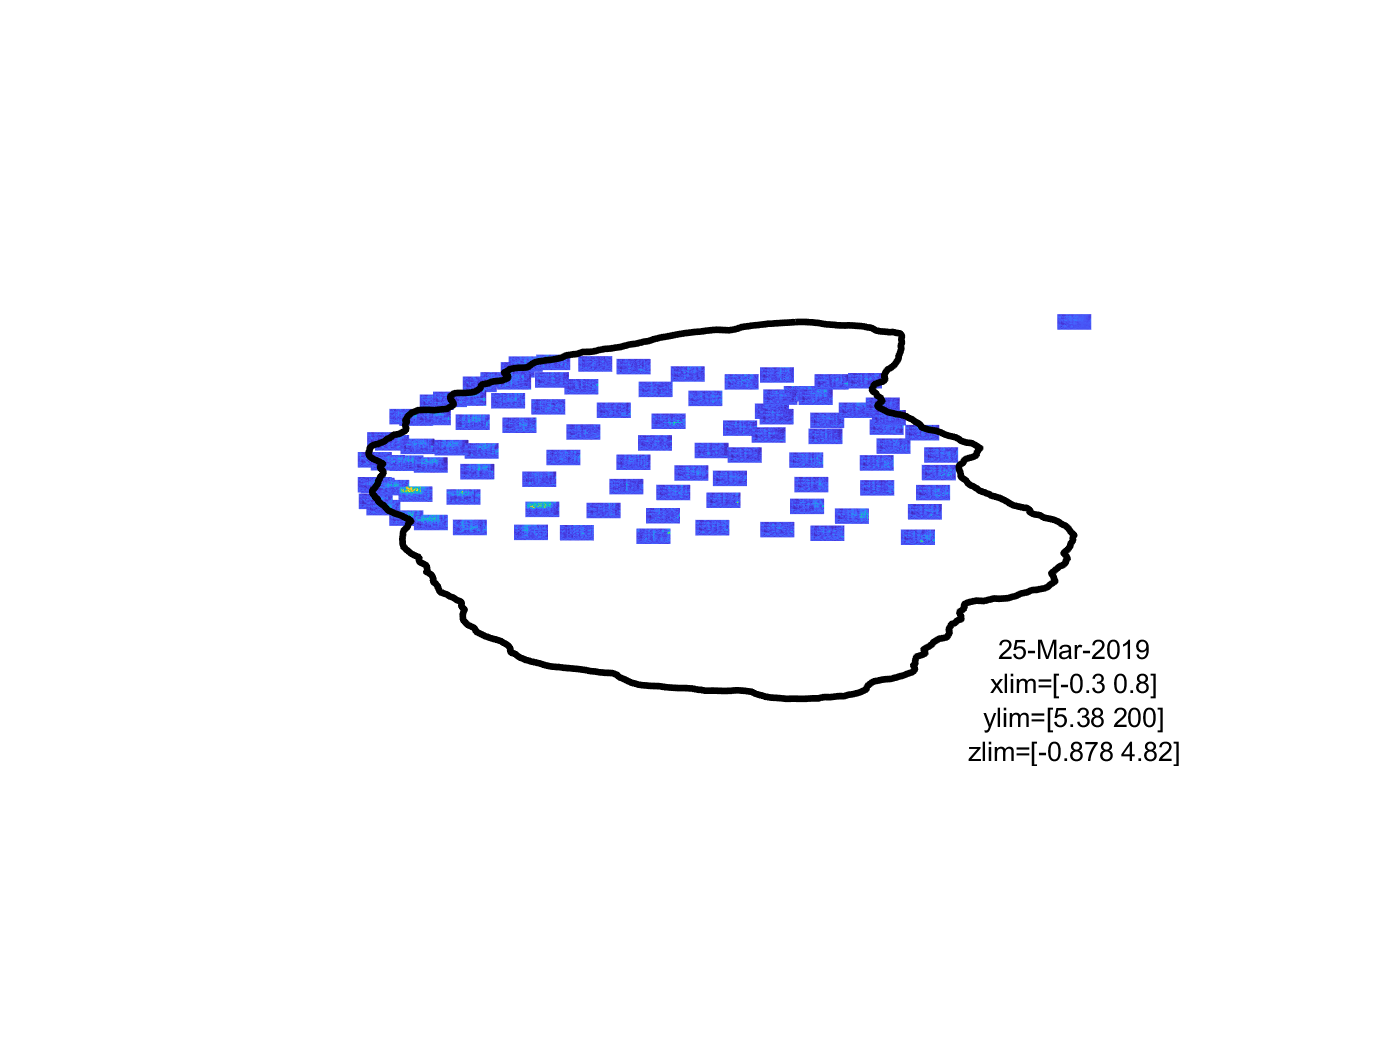

the call to "ft_multiplotTFR" took 2 seconds


cfg             = [];
cfg.layout      = lay;
cfg.showoutline = 'yes';
ft_multiplotTFR(cfg, freq_blc);


% this brain figure is interactive: can draw 1 or more boxes over channels
% and it will produce an average time-frequency plot across those channels.
% that next figure is also interactive: can select a time x frequency range
% in that figure at it will produce a new figure with the spatial
% distribution of that signal across the electrodes

## **ECoG data representation**

- For an anatomically realistic representation of cortical activity,  overlay a surface model of the neocortex with the spatial distribution  of the high frequency-band activity. First, extract mean  high-frequency-band activity during a time interval of interest.

cfg             = [];
cfg.frequency   = [70 150];
cfg.avgoverfreq = 'yes';
cfg.latency     = [0 0.8];
cfg.avgovertime = 'yes';
freq_sel = ft_selectdata(cfg, freq_blc);

the call to "ft_selectdata" took 0 seconds


- Visualize the spatial distribution of high-frequency-band activity on a cortical mesh of the subject’s brain.

cfg              = [];
cfg.funparameter = 'powspctrm';
cfg.funcolorlim  = [-.5 .5];
cfg.method       = 'surface';
cfg.interpmethod = 'sphere_weighteddistance';
cfg.sphereradius = 8;
cfg.camlight     = 'no';
ft_sourceplot(cfg, freq_sel, pial_lh);

the input is freq data with 145 channels, 1 frequencybins and 1 timebins
the call to "ft_selectdata" took 0 seconds
the input is mesh data with 117024 vertices and 234044 triangles
the input is source data with 117024 brainordinates


 In getdimord>warning_dimord_could_not_be_determined at line 632
 In getdimord at line 581
 In getdatfield at line 45
 In ft_datatype_source at line 232
 In ft_checkdata at line 282
 In ft_sou

 In getdimord>warning_dimord_could_not_be_determined at line 632
 In getdimord at line 581
 In ft_datatype_source at line 234
 In ft_checkdata at line 282
 In ft_sourceinterpolate at line 162
 In ft_sourcepl

The source functional is defined on a triangulated surface, using the surface mesh description in the functional


 In ft_plot_mesh at line 184
 In ft_sourceplot at line 1253

the call to "ft_sourceplot" took 1 seconds


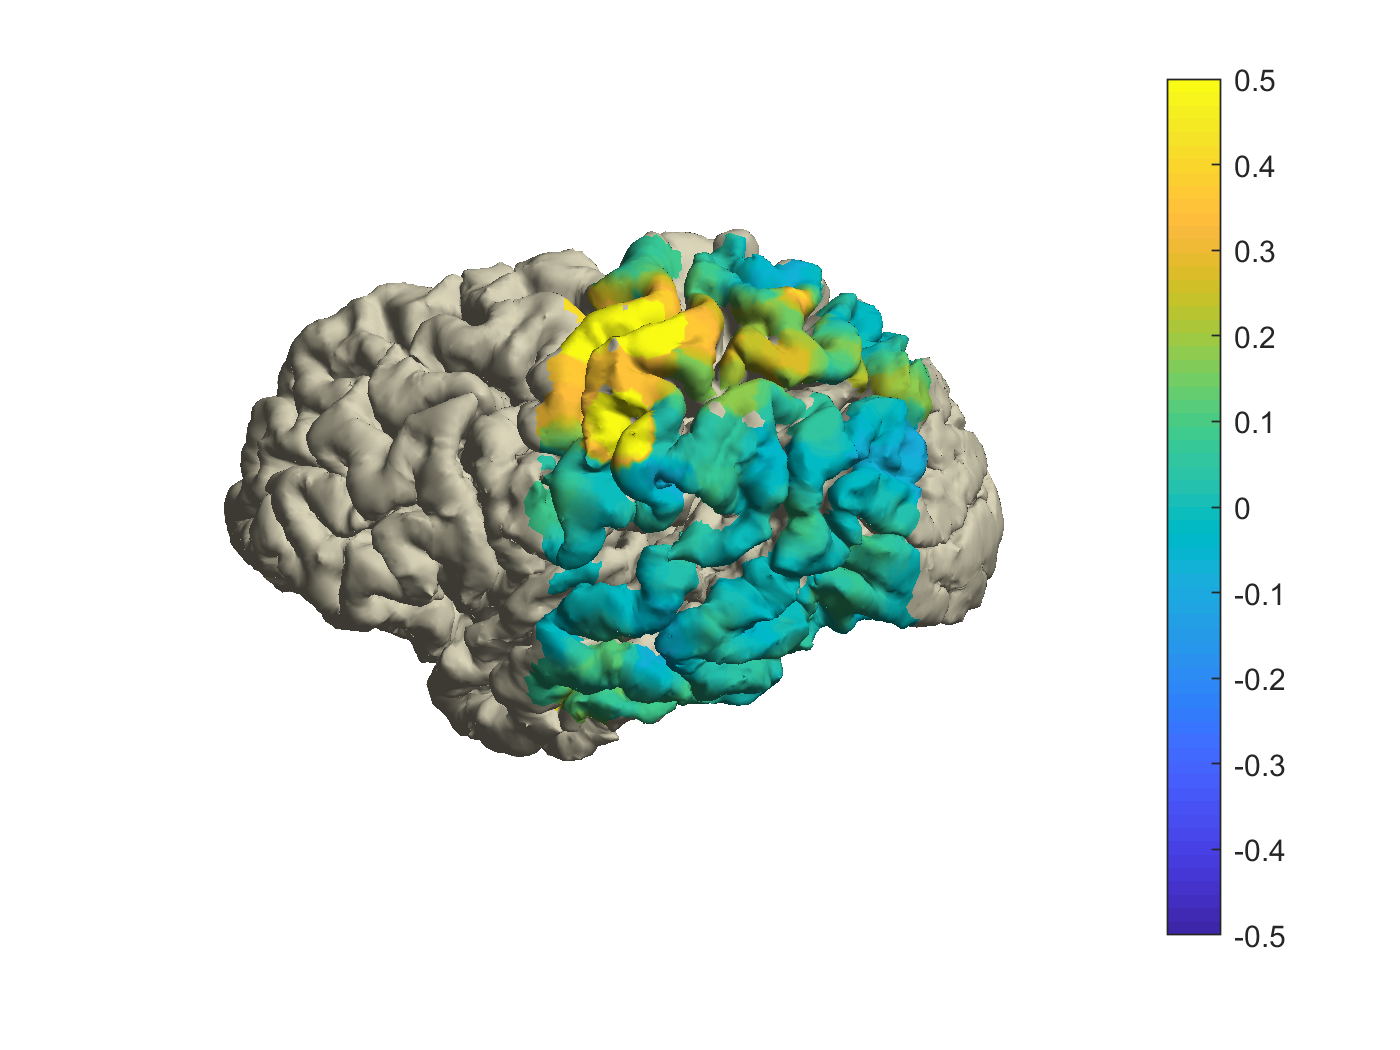

view([-90 20]);
material dull;
lighting gouraud;
camlight;

- Add the electrodes to the figure (shown below). By looping around Steps  50 and 51 while breaking down the time interval of interest specified  with cfg.latency in consecutive steps, it becomes feasible to observe  the spatiotemporal dynamics of neural activity occurring in relation to  known experimental structure and behavior ([Supplementary Video 6](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM11_ESM.mp4)). See help getframe for capturing and assembling time-lapse movies.

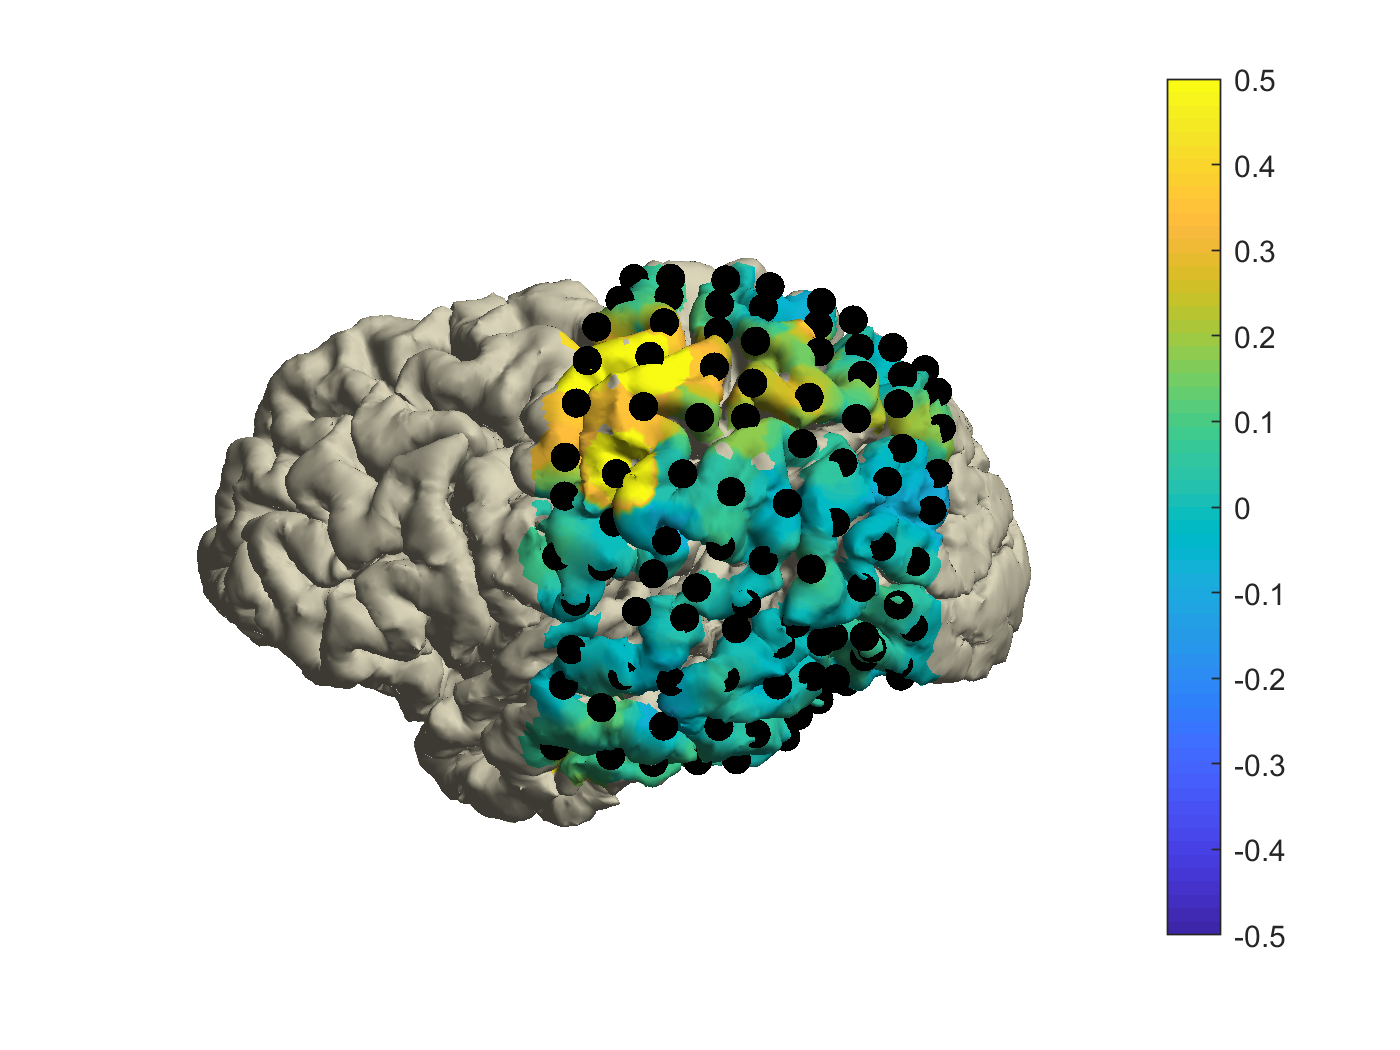

ft_plot_sens(elec_acpc_fr);

## **SEEG data representation**

- For depth recordings, create an integrated representation of neural  activity and anatomy by interpolating neural data from each bipolar  channel in a spherical cloud, which can then be overlaid on a surface  mesh of any deep brain structure. First, create a volumetric mask of the regions of interest. Here, we generate a mask for the right hippocampus and amygdala from the cortical parcellation and subcortical  segmentation produced by FreeSurfer.

NOTE: these steps requires FreeSurfer, which does not work natively on Windows

% atlas = ft_read_atlas('freesurfer/mri/aparc+aseg.mgz');
% atlas.coordsys = 'acpc';
% cfg            = [];
% cfg.inputcoord = 'acpc';
% cfg.atlas      = atlas;
% cfg.roi        = {'Right-Hippocampus', 'Right-Amygdala'};
% mask_rha = ft_volumelookup(cfg, atlas);

- Create a triangulated and smoothed surface mesh on the basis of the volumetric masks.

% seg = keepfields(atlas, {'dim', 'unit','coordsys','transform'});
% seg.brain = mask_rha;
% cfg             = [];
% cfg.method      = 'iso2mesh';
% cfg.radbound    = 2;
% cfg.maxsurf     = 0;
% cfg.tissue      = 'brain';
% cfg.numvertices = 1000;
% cfg.smooth      = 3;
% cfg.spmversion  = 'spm12';
% mesh_rha = ft_prepare_mesh(cfg, seg);

- Identify the subcortical electrodes of interest.

% cfg         = [];
% cfg.channel = {'RAM*', 'RTH*', 'RHH*'};
% freq_sel2 = ft_selectdata(cfg, freq_sel);

- Interpolate the high-frequency-band activity in the bipolar channels on a spherical cloud around the channel positions, while overlaying the  neural activity with the above mesh ([Supplementary File 4](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM1_ESM.pdf) highlights the currently available cloud types for plotting). By  repeating the current step for neural data corresponding to consecutive  time intervals, similarly to the process outlined in Step 52, it becomes feasible to create time-lapse movies of the spatiotemporal dynamics of  deep-brain activity ([Supplementary Video 7](https://static-content.springer.com/esm/art%3A10.1038%2Fs41596-018-0009-6/MediaObjects/41596_2018_9_MOESM12_ESM.mp4) shows the spatiotemporal evolution of epileptiform activity in a separate subject).

% cfg              = [];
% cfg.funparameter = 'powspctrm';
% cfg.funcolorlim  = [-.5 .5];
% cfg.method       = 'cloud';
% cfg.slice        = '3d';
% cfg.nslices      = 2;
% cfg.facealpha    = .25;
% ft_sourceplot(cfg, freq_sel2, mesh_rha);
% view([120 40]);
% lighting gouraud;
% camlight;

- To create a more definitive image of the neural activity at particular  positions, generate two-dimensional slices through the three-dimensional representations. This combination provides the most complete and  integrated representation of neural and anatomical data (figure below).

% cfg.slice        = '2d';
% ft_sourceplot(cfg, freq_sel2, mesh_rha);